# Projet 4.5 - Séparation de sources Audio

# **Représentation parcimonieuse et acquisitions compressées**

**Notebook de présentation.**

Les méthodes utilisées sont inspirées de : 

- *Rémi Gribonval, Sylvain Lesage. *

*A survey of Sparse Component Analysis for blind source separation: principles, perspectives, and new challenges.*

*ESANN’06 proceedings - 14th European Symposium on Artificial Neural Networks, Apr 2006, Bruges, Belgium. pp.323–330. inria-00544897* 

- Handbook of Blind Source Separation 			

Independent Component Analysis and Applications 				

**Edited by P. Comon and C. Jutten **

Attention, faites en sorte d'avoir :

- **Audio Toolbox (Pour des raisons évidentes)**

- **Signal Processing Toolbox**

- **Curve fitting Toolbox (pour pouvoir lisser la courbe de l'histogramme)**

- **Assez de RAM** 

## Étape 1 - Avoir une source et la caractériser

Dans un premier temps, nous allons importer un signal audio sur lequel travailler.

Ici, je ne prendrai que les 10 premières secondes d'un signal, dans le souci de soulager nos processeurs, déjà très sollicités par l'UI de Matlab.

J'ai P=**2 observations** de mon mélange (les deux mono qui forment le stereo), et** 3 sources.**

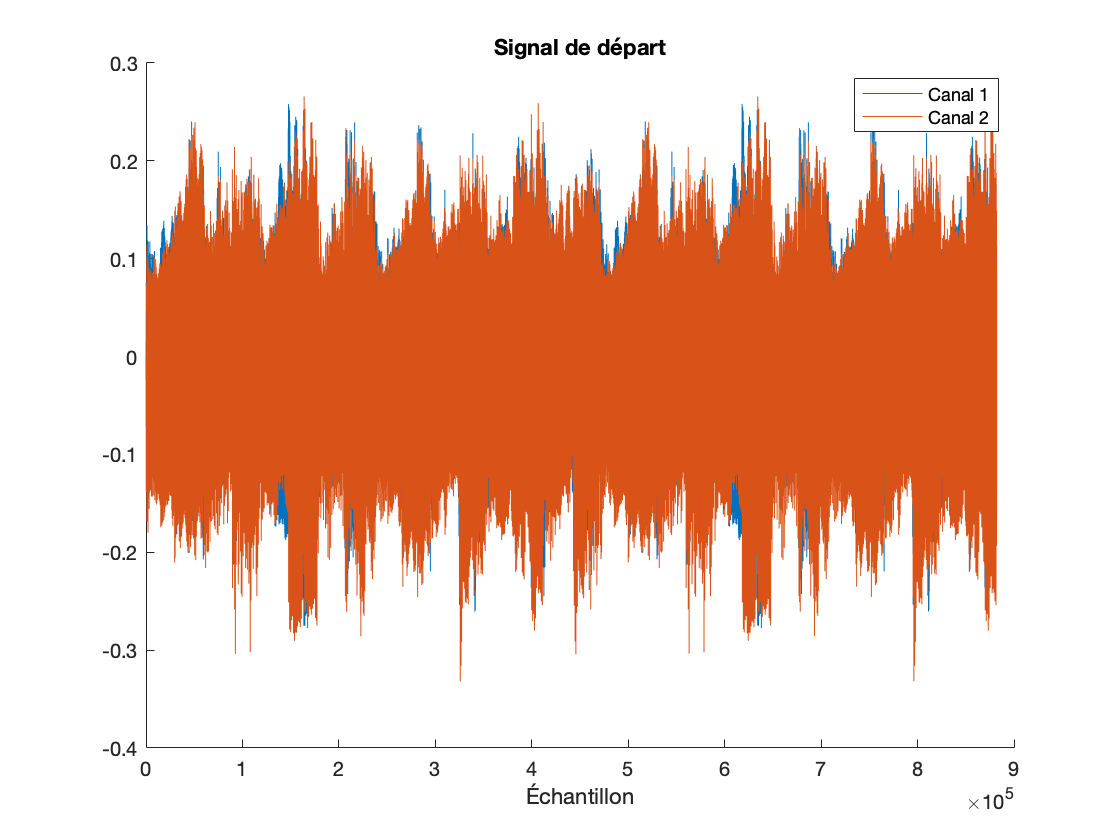

[~,Fs] = audioread('pia_vio_bas.wav');
samples = [1,20*Fs];     %Je ne prends que les 20 premières secondes
clear y Fs
[x,Fs] = audioread('pia_vio_bas.wav',samples);

%Ordre des instruments : gauche mid droite donné dans le nom du fichier

m =2;   %Nombre de canaux
x1 = x(:,1);  %J'ai séparé les deux canaux, parce que Stereo
x2 = x(:,2);
%x1 = x1(1:4:end);
%x2 = x2(1:4:end);


%Nombre d'éléments du signal
T = length(x);

%Durée d'observation, en secondes
Tobs = T / Fs;

%Plot
figure;
title('Signal de départ')
xlabel("Échantillon")

hold on;
plot(x1);
plot(x2)
legend('Canal 1','Canal 2');
hold off

Dans la section suivante, j'importe les différentes sources individuelles pour pouvoir les comparer à nos solutions potentielles


[s1, ~] = audioread("piano_arpeges.wav", samples);
[s2, ~] = audioread("violin_4.wav", samples);
[s3, ~] = audioread("bass.wav", samples);
%Ce sont nos sources au départ, ça peut servir

s1 = s1(:,1);
s2 = s2(:,1);
s3 = s3(:,1);
%Je ne prends qu'un canal


## Étape 2 - Parcimonier !

Je vais maintenant transformer ce sur quoi je travaille. En effet, je vais passer dans un autre domaine, et utiliser :

la ***modified discrete cosine transform, ***et la*** short-timed Fourier transform***

On qualifiera ces transformées de ***sparsifying linear transforms --> ***Elle vont, a fortiori, rendre nos données parcimonieuses. 

C'est afin de pouvoir comparer les méthodes que nous utiliserons deux transformations.

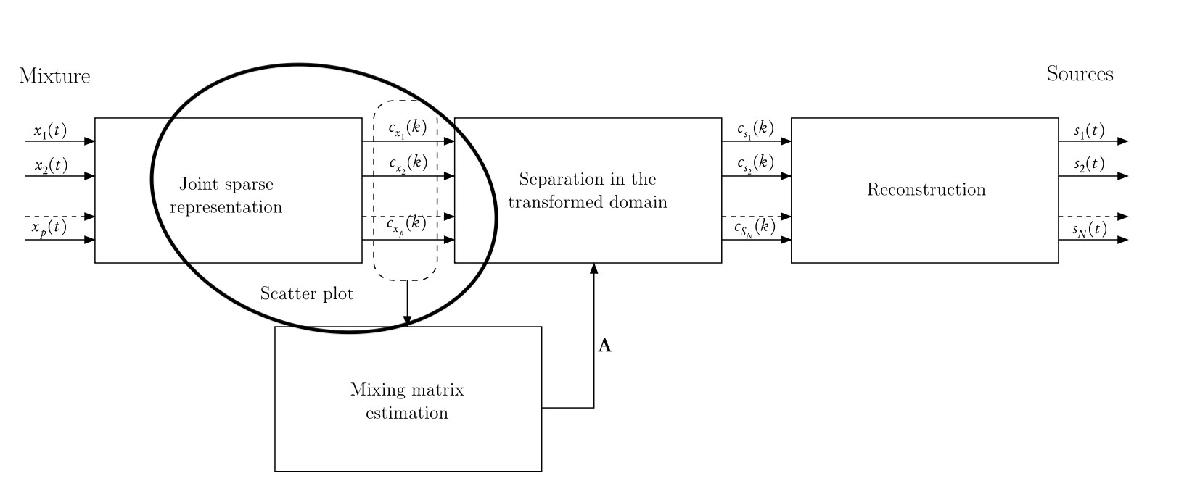

En effet, dans les faits les signaux audio sont tout sauf parcimonieux à la base. 

C'est un problème à dominantes multiples (Les sources sont actives simultanément), ce qui rend la chose bien plus difficile.  

Pour appliquer nos transformées, nous devons définir des fenêtres sur lesquelles appliquer nos transformations. 

win_size = 1024;  %On définit leur tailles en nombres d'éléments

% On peut déjà commencer par une fenêtre rectangulaire. Simple, efficace
win = rectwin(win_size);

*La section suivante contient le code utilisant la ****MDCT***

cx1 = mdct(x1,win);             %Un canal
cx2 = mdct(x2, win);            %l'autre
coeff_size = size(cx1);  %Permet de se rendre compte que mdct renvoie une matrice ! 


Affichage de nos coefficients sous la forme d'un spectrogramme

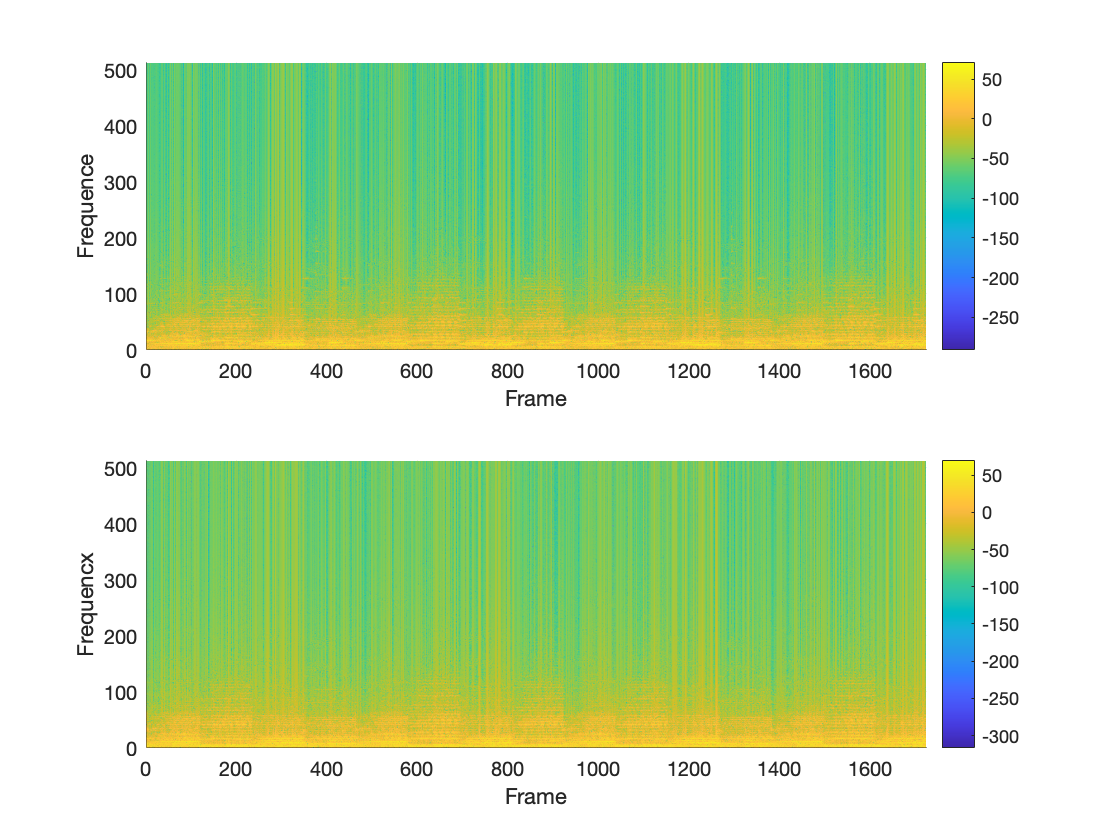

subplot(2,1,1);
surf(20*log10(cx1.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequence')
axis([0 size(cx1,2) 0 size(cx1,1)])
colorbar
subplot(2,1,2);
surf(20*log10(cx2.^2),'EdgeColor','none'); %plot une surface
view([0 90])
xlabel('Frame')
ylabel('Frequencx')
axis([0 size(cx2,2) 0 size(cx2,1)])
colorbar

Cette cellule ci utilise la** STFT** (short-timed Fourier Transform), avec la fonction spectrogram() déjà implémentée .

[S1,F1,T1] = spectrogram(x1,win,win_size/2);   %STFT
[S2,F2,T2] = spectrogram(x2,win,win_size/2);    %STFT 


S = [S1(:) S2(:)];      %Vectorisation, puis concaténations des coefficients de chaque canal

Nous avons donc calculer nos coefficients associés à nos deux transformations. 

Tracer l'histogramme permet de voir si on a une distribution parcimonieuse.

Ici, nos coefficients de transformée sont complexes, j'affiche donc la valeur absolue de ces coefficients.

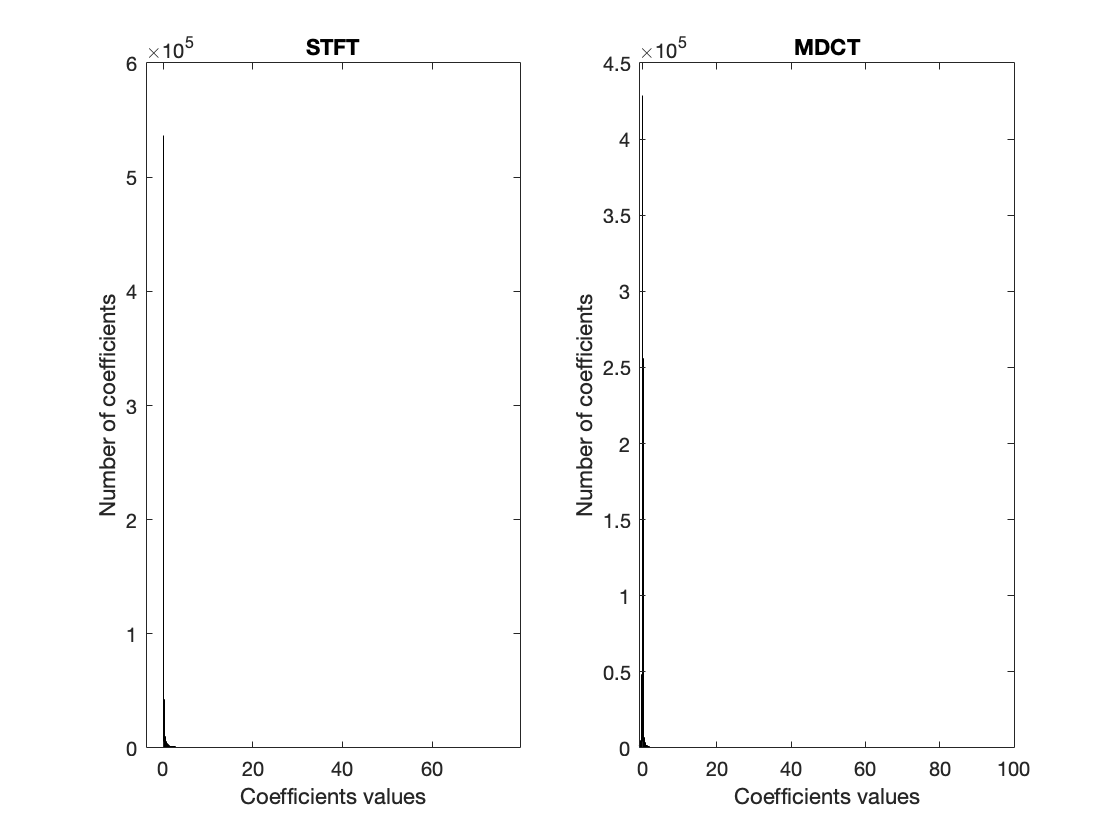

figure;
subplot(121)
histogram(abs(S1),1000);    %Assez peu représentatif, on ne se rend pas bien compte de ce qu'il se passe
                            % de ce qu'il se passe dans voisinage plus
                            % petit de 0
title('STFT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
subplot(122)                           
histogram(cx1,1000);     
title('MDCT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 100])  

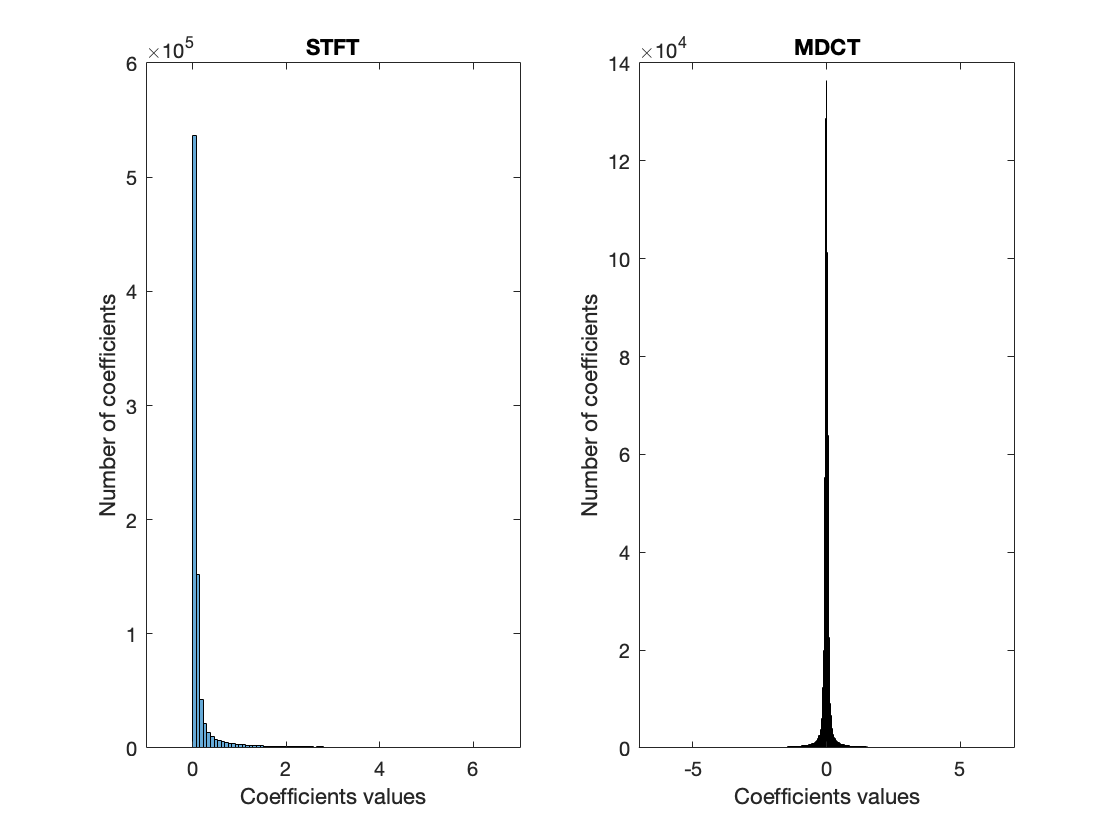


figure;  %Pour regarder de plus près autour de 0
subplot(121)
histogram(abs(S1),1000);
title('STFT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 7])

subplot(122)
histogram(cx1,5000);
title('MDCT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-7 7])

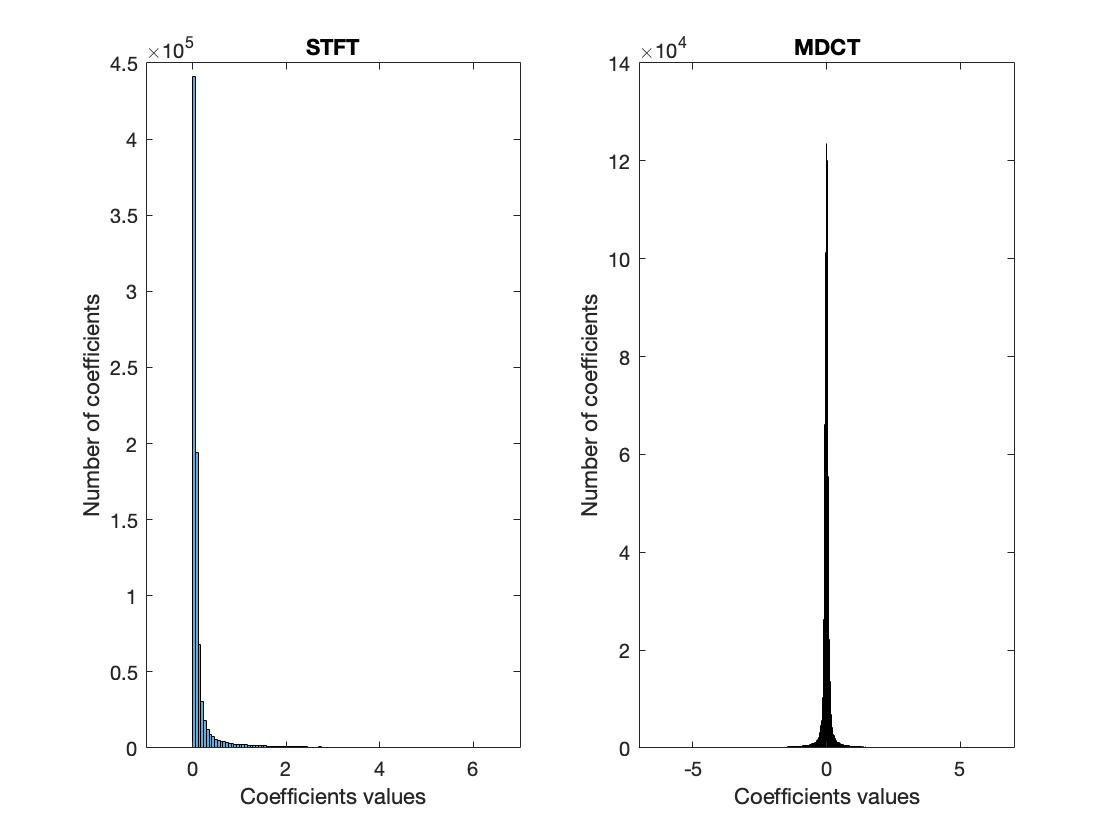


figure;  %Pour regarder de plus près autour de 0
subplot(121)
histogram(abs(S2),1000);
title('STFT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-1 7])

subplot(122)
histogram(cx2,5000);
title('MDCT')
xlabel('Coefficients values')
ylabel('Number of coefficients')
xlim([-7 7])

**Étant donné qu'on a pic pour des valeurs très petites, on peut se dire que c'est le cas : **

**on a plein de valeurs considérées comme quasi-nulles. **

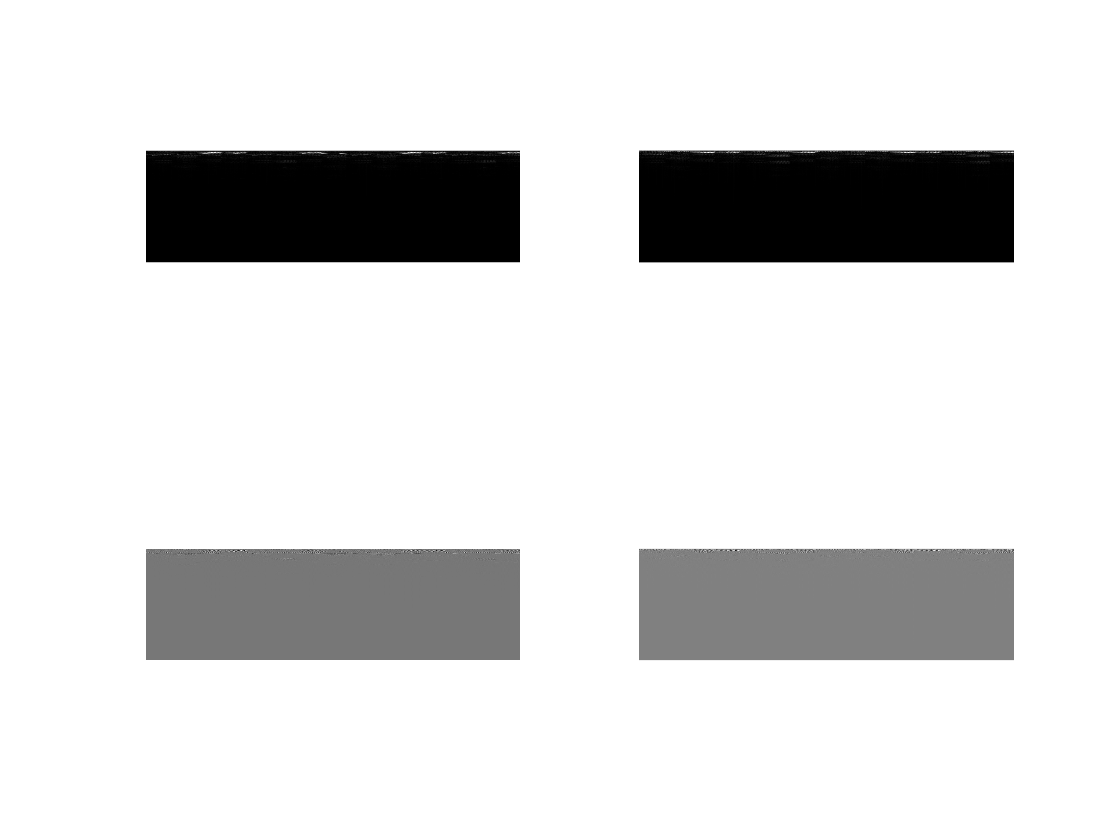


%Je trouvais sympathique, pour montrer la parcimonie, de visionner des
%images.

figure;
title("Illustration de la parcimonie dans nos coefficients")

ax1 = subplot(2,2,1);
M1 = mat2gray(abs(S1));
title("STFT canal 1")
imshow(M1);

ax2 = subplot(2,2,2);
M2 = mat2gray(abs(S2));
title("STFT canal 2")
imshow(M2);

ax3 = subplot(2,2,3);
xlabel("MDCT canal 1")
M3 = mat2gray(cx1);
imshow(M3);

ax4 = subplot(2,2,4);
title("MDCT canal 2")
M4 = mat2gray(cx2);
imshow(M4);

A présent, visualisons nos Scatter plot, et voyons s'ils ont l'air cohérents !

Les scatter plot correspondent aux nuages de points (c1(k), c2(k)) avec 1<k<K

Ici, avec deux canaux, nous avons deux dimensions.

Nous nous attendons à voir des directions distinctes : 

***MDCT***

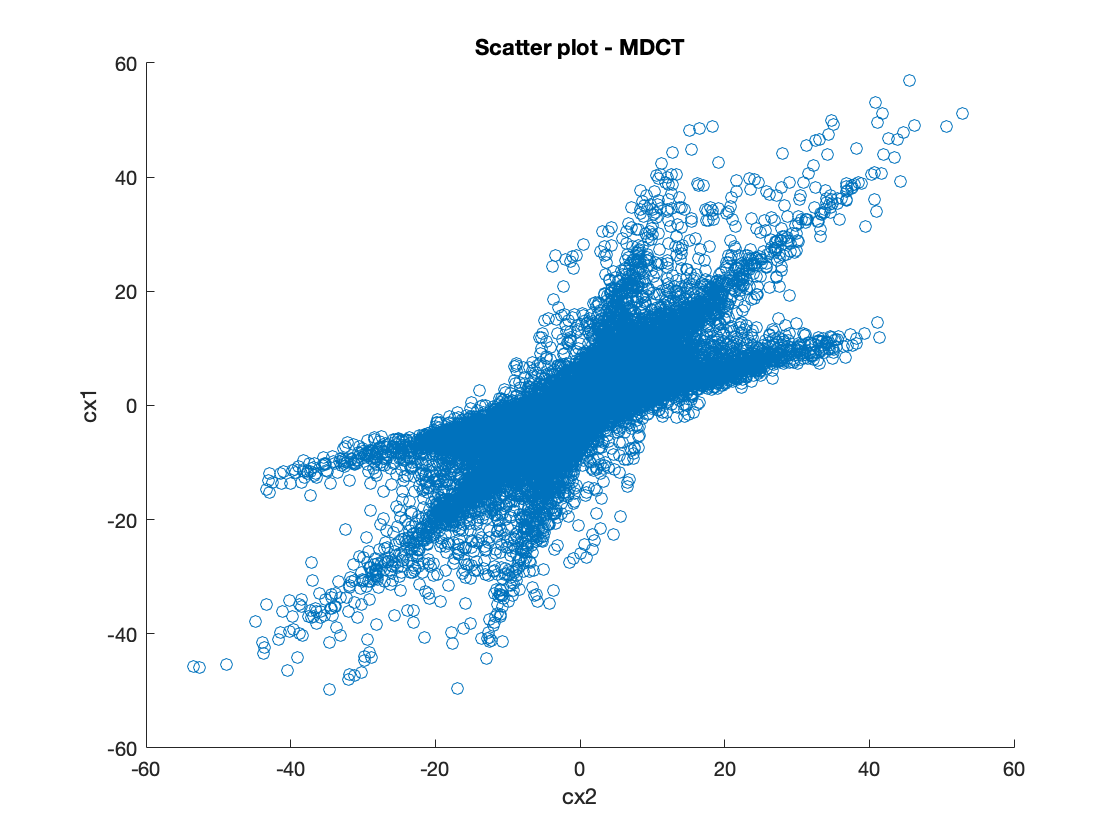

c1 = cx1(:); 
c2 = cx2(:);    % Vectorisation

figure;
scatter(c2,c1);
title("Scatter plot - MDCT")
xlabel('cx2')
ylabel('cx1')

***STFT***

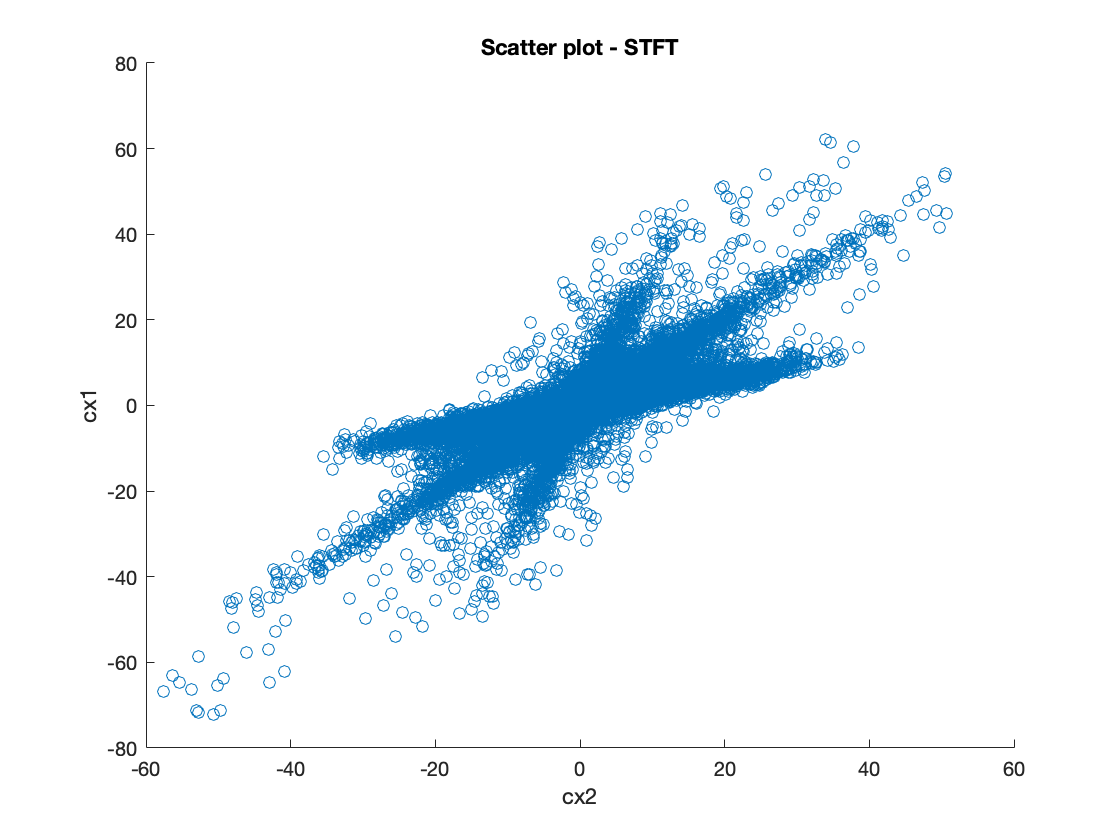

figure;
scatter(real(S2(:)), real(S1(:)));     %rappel : nos coefficients de STFT sont complexes!
title("Scatter plot - STFT")
xlabel('cx2')
ylabel('cx1')

**Nous voyons bien ici trois directions ! **

On se rend compte que les directions principales sont moins dispersées avec la STFT.

## Étape 3 - Estimation de la *Mixing Matrix*

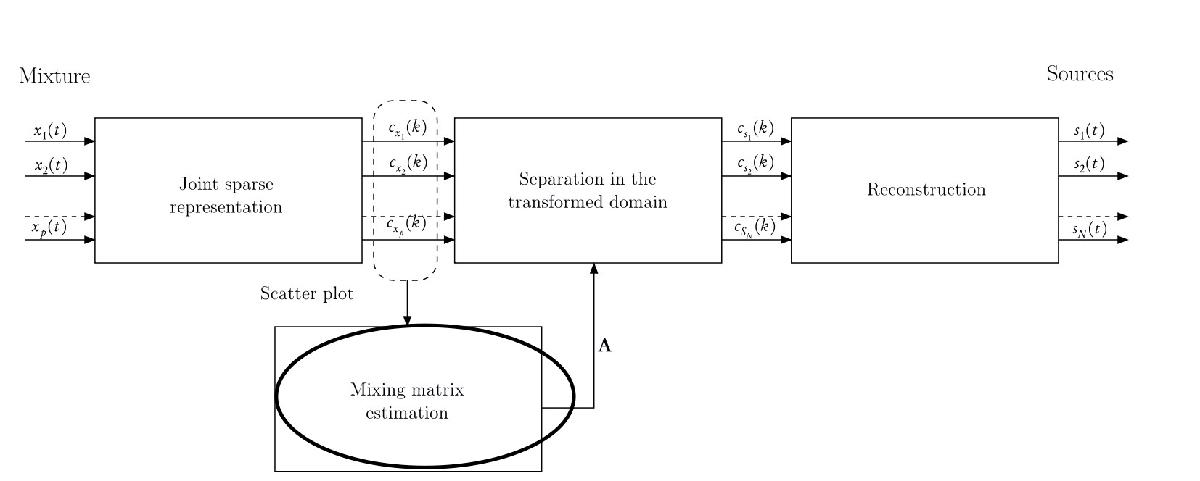

La matrice de mélange, que l'on notera A, représente le mélange de nos différentes sources, qui composent notre signal final. 

Pour coller aux notations du Handbook, je vais construire la matrice Cx, qui correspond à : 

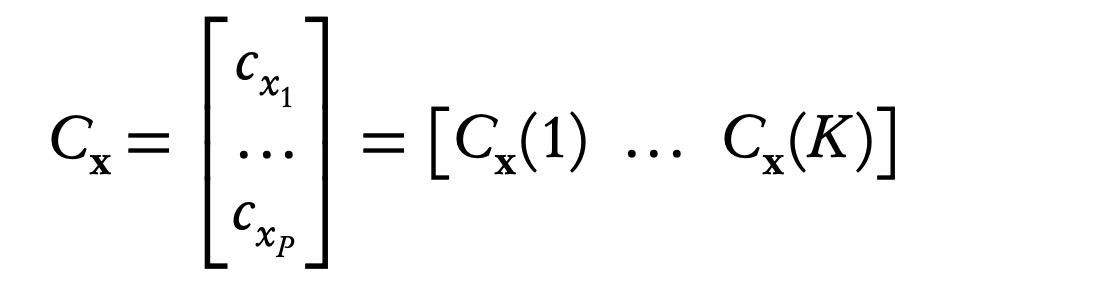

cf équation 10.12

Le but est d'estimer la n-ième colonne de A, et la direction qui correspond.

***STFT***

Cx_stft = [abs(S1(:))' ;  abs(S2(:))'];
Csize_stft = size(Cx_stft);
rho = zeros([1 Csize_stft(2)]);
theta = zeros([1 Csize_stft(2)]);


for k = 1:length(Cx_stft)
    theta(k) = atan(Cx_stft(2,k)/Cx_stft(1,k));
    rho(k) = sqrt(abs(Cx_stft(2,k))^2  + abs(Cx_stft(1,k))^2);
    if theta(k)<0
        theta(k) = theta(k) + pi;
        rho(k) = -sqrt(abs(Cx_stft(2,k))^2  + abs(Cx_stft(1,k))^2);
    end           
end

***MDCT***

Cx_mdct = [cx1(:)' ;  cx2(:)']; 
Csize_mdct = size(Cx_mdct);
rho_mdct = zeros([1 Csize_mdct(2)]);
theta_mdct = zeros([1 Csize_mdct(2)]);

for k = 1:length(Cx_mdct)
    theta_mdct(k) = atan(Cx_mdct(2,k)/Cx_mdct(1,k));
    rho_mdct(k) = sqrt(abs(Cx_mdct(2,k))^2  + abs(Cx_mdct(1,k))^2);
    if theta_mdct(k)<0
        theta_mdct(k) = theta_mdct(k) + pi;
        rho_mdct(k) = -sqrt(abs(Cx_mdct(2,k))^2  + abs(Cx_mdct(1,k))^2);
    end           
end

***Affichages des directions trouvées***

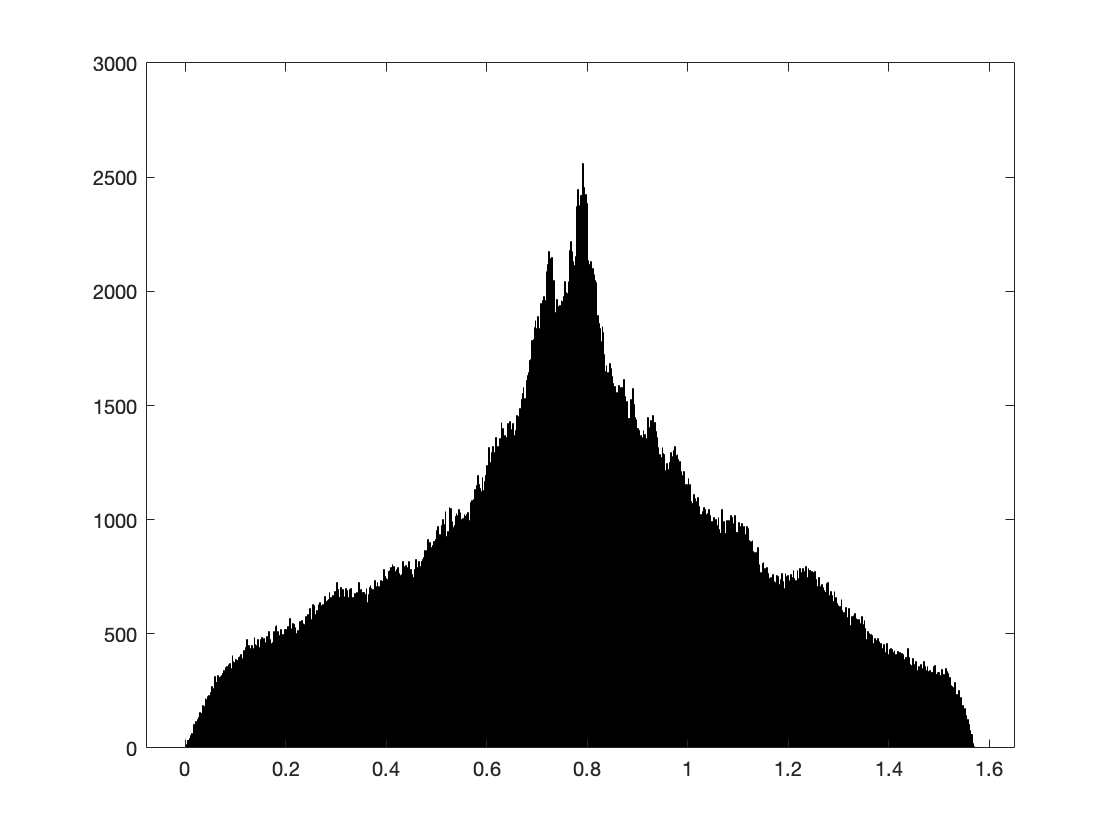

figure;
histogram(theta,1000);

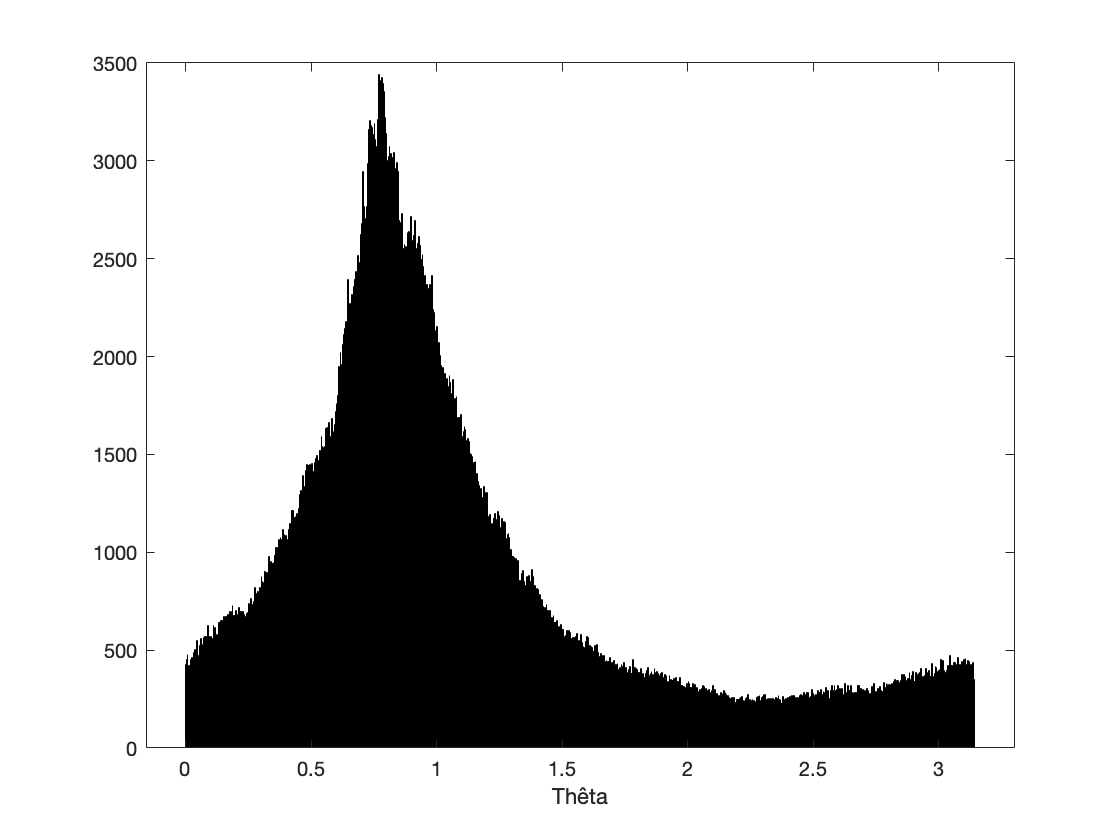



figure;
histogram(theta_mdct,1000);
xlabel('Thêta')

Dans ces histogrammes bruts, les directions ne transparaissent pas.

Heureusement, nous utiliserons un histogramme pondéré !

On va donc définir notre fonction de lissage (qui sera exponentielle), et l'appliquer à nos valeurs de thêta.  cf équation 10.35 remaniée pour pas utiliser Parzen de la Vallée Poussin

smoothing_win = rectwin(win_size);  
theta_l = linspace(0,pi,win_size+1);
H = zeros(1,win_size+1);
for l =1:win_size+1
    for k = 1:Csize_stft(2)
        H(l) = H(l) + rho(k) * exp(-((theta_l(l)-theta(k))^2) /0.0001);
    end
end

Afficher le module de nos points en fonction de leur module permet déjà de se rendre compte qu'il existe 3 directions.

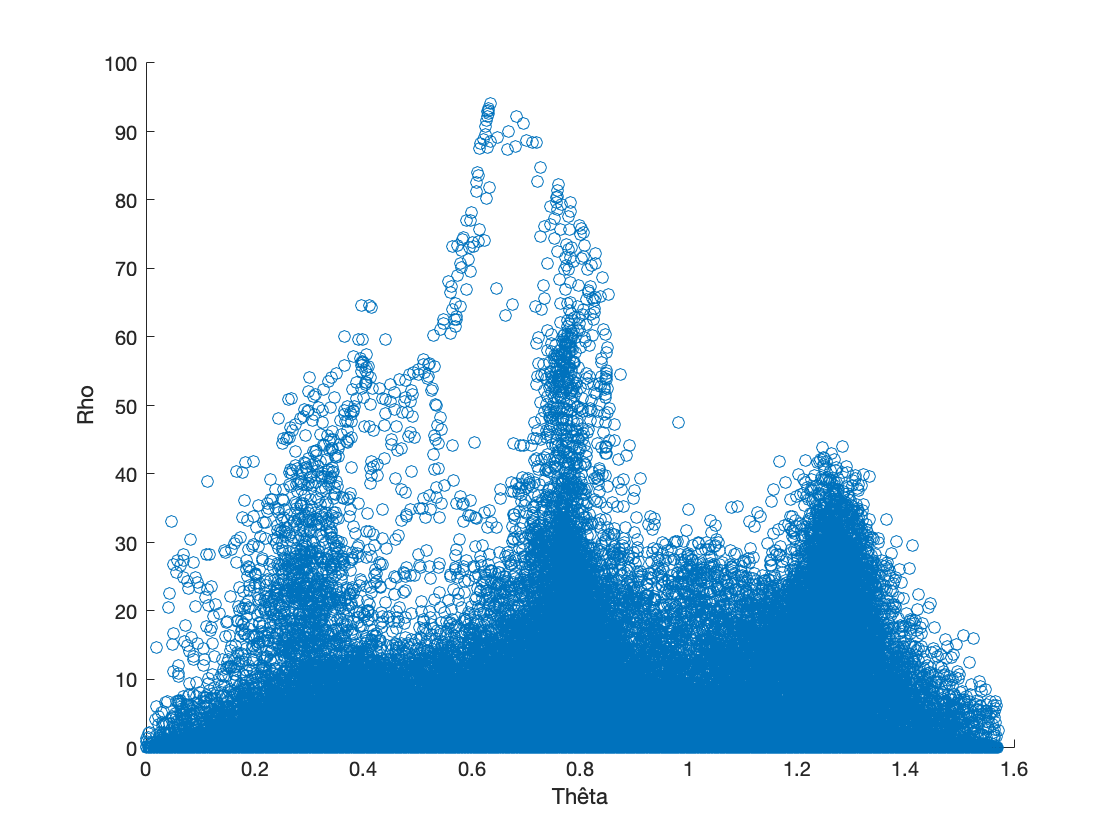

figure;
scatter(theta,rho)
xlabel('Thêta')
ylabel('Rho')

On voit bien trois directions qui se démarquent. 

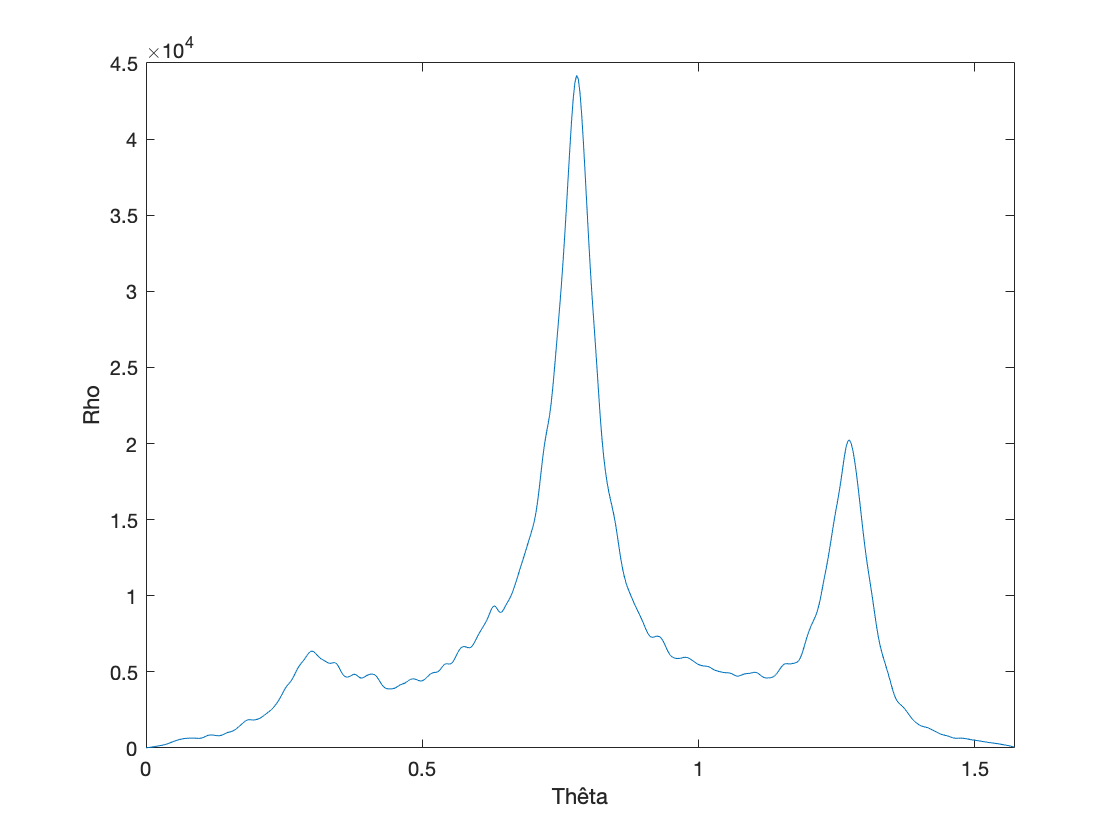

figure;
plot(theta_l,H)
xlabel('Thêta')
ylabel('Rho')
xlim([0 pi/2])

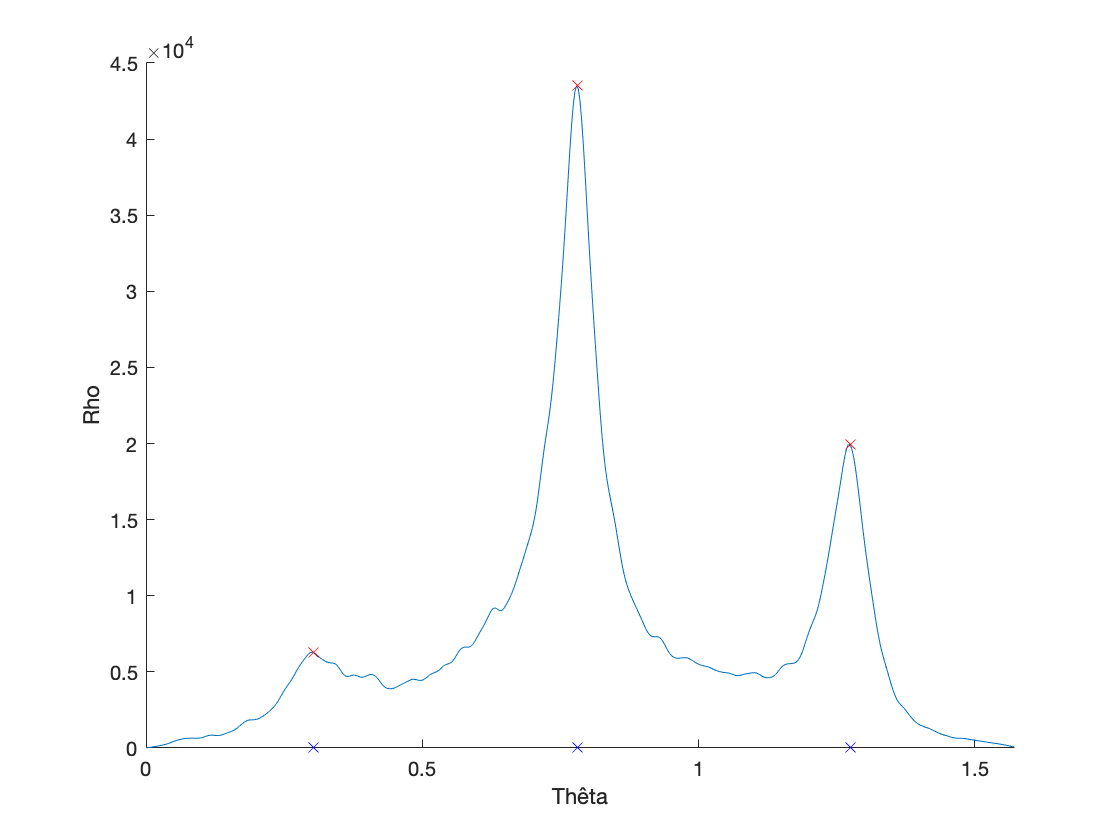

H = smooth(H);  %Permet de lisser légèrement l'histogramme continu, 
                % afin d'éviter de confondre aspérités et pics
                
[peaks, locs] = findpeaks(H,"MinPeakWidth",15); %Là encore, préciser une largeur minimale
                                                % pour les pics permet d'éviter de confondre 
                                                % aspérités et pics. Ne
                                                % convient pas à tous les
                                                % signaux.
                                                
locs = pi*locs ./ 1025;  %1025 est la taille du vecteur theta_l

figure;
hold on
plot(theta_l,H)
plot(locs,peaks,'x',"Color",'r')   %Situe les pics
plot(locs,locs,'x',"Color",'b')    %Précise les abscisse des pics
xlabel('Thêta')
ylabel('Rho')
hold off
xlim([0, pi/2])

Youpi, des pics et des directions associées ! 

On construit donc notre matrice A. Attention ! La matrice A présentée dans le handbook concerne la MDCT, il faut donc la remanier pour la STFT

***MDCT***

A1_mdct = [cos(locs(1)) sin(locs(1))]';  %L'apostrophe permet de transposer le vecteur, et d'en faire un vecteur colonne
A2_mdct = [cos(locs(2)) sin(locs(2))]';
A3_mdct = [cos(locs(3)) sin(locs(3))]'; 

A_mdct= [A1_mdct A2_mdct A3_mdct];

***STFT***

%RIP

## Étape 4 - Séparation en composantes indépendantes

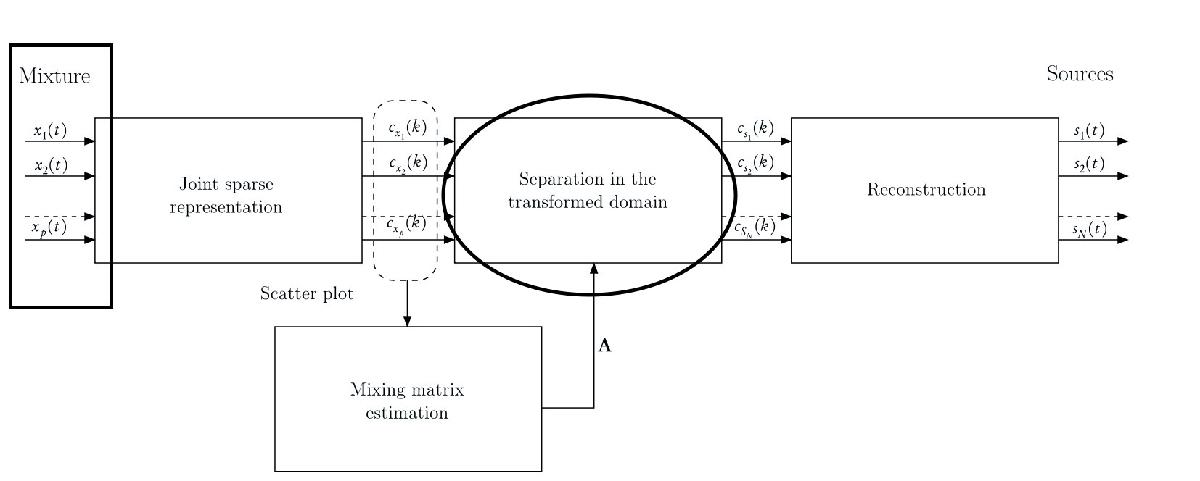

Premier essai avec la pseudo_inverse de A

Second essai avec l'Orthogonal Matching Pursuit

%LS
Cs_mdct_pinv =  pinv(A_mdct)*Cx_mdct;   

Cs1_mdct_pinv = reshape(Cs_mdct_pinv(1,:),coeff_size(1),coeff_size(2));
Cs2_mdct_pinv = reshape(Cs_mdct_pinv(2,:),coeff_size(1),coeff_size(2));
Cs3_mdct_pinv = reshape(Cs_mdct_pinv(3,:),coeff_size(1),coeff_size(2));

%OMP
Cs_mdct_omp = OMP(A_mdct,Cx_mdct,1);
Cs1_mdct_omp = reshape(Cs_mdct_omp(1,:),coeff_size(1),coeff_size(2));
Cs2_mdct_omp = reshape(Cs_mdct_omp(2,:),coeff_size(1),coeff_size(2));
Cs3_mdct_omp = reshape(Cs_mdct_omp(3,:),coeff_size(1),coeff_size(2));

**Étape 5 - Reconstruction**

Il est maintenant temps de revenir à notre domaine de départ, en effectuant une transformée inverse, avec la fonction *imdct, *et de tirer nos premières conclusions !

s1_mdct = imdct(Cs1_mdct_pinv,rectwin(win_size));   %Piano
s2_mdct = imdct(Cs2_mdct_pinv,rectwin(win_size));   %Violon
s3_mdct = imdct(Cs3_mdct_pinv,rectwin(win_size));   %Basse

s1_mdct_omp = imdct(Cs1_mdct_omp,rectwin(win_size));  %Piano
s2_mdct_omp = imdct(Cs2_mdct_omp,rectwin(win_size));  %Violon
s3_mdct_omp = imdct(Cs3_mdct_omp,rectwin(win_size));  %Basse

## **Les moindres-carrés nous permettent d'avoir un premier résultat qui, bien qu'il soit un pas dans la bonne direction, ne sont pas assez satisfaisants.**

Les instruments ne sont pas isolés, ils sont simplement accentués par rapport aux autres. 

## **Heureusement, nous nous rendons compte que l'Orthogonal Matching Pursuit nous permet d'obtenir des résultats plus convaincants.**

Malgré quelques grésillements intempestifs, et des résidus des autres sources, nous pouvons reconnaitre les différents instruments, et les considérer comme isolés.

piano = s1_mdct_omp;
violon = s2_mdct_omp;
basse = s3_mdct_omp;


%soundsc(piano,Fs);
%soundsc(violon,Fs);
%soundsc(basse,Fs);

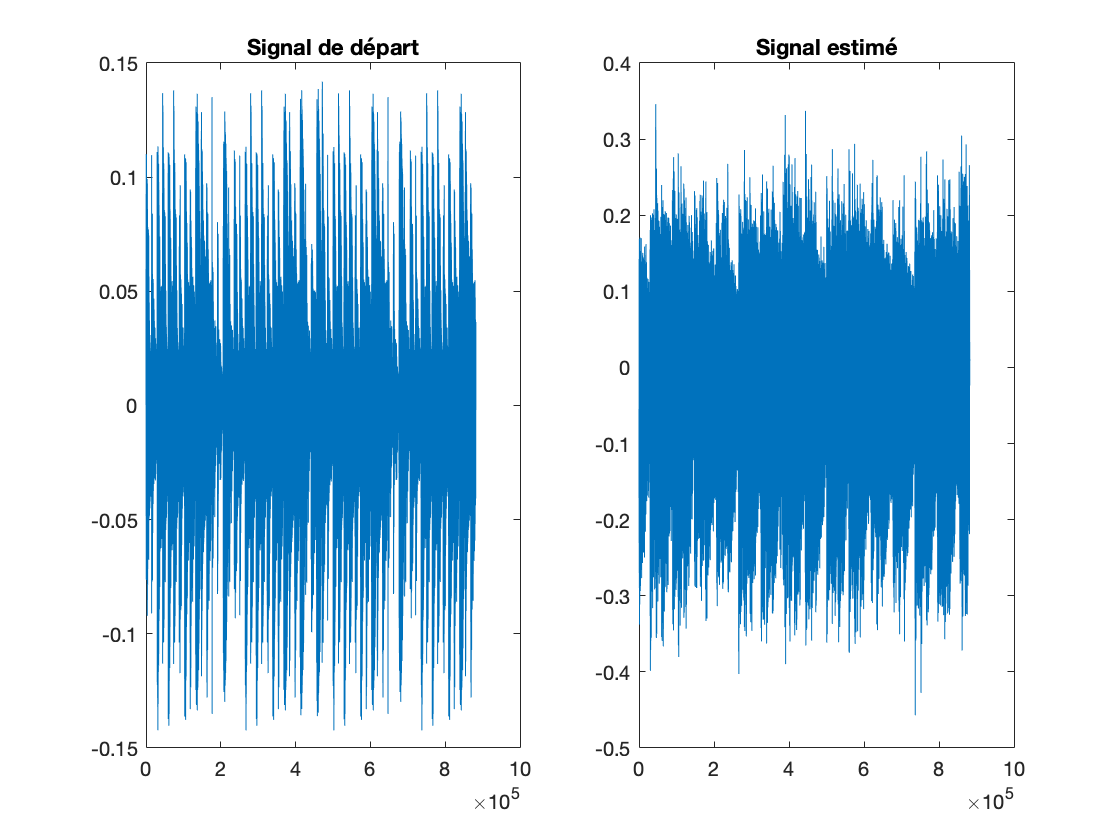

%Basse
figure;
subplot(121)
plot(s1)
title('Signal de départ')
subplot(122)
plot(basse)
title('Signal estimé')

    